# PROYECTO 3: MECÁNICA CELESTE

## EQUIPO N°1

- Mariana Zapata Covarrubias 195111

- Mauricio Verduzco Chavira 195106

- Ricardo Illescas Carrancá 197809

- Alejandro Terrazas Maeshiro 187977

## IDENTIFICACIÓN DEL PROBLEMA

### Identificación del problema

Después de más de 20 años de investigación, aún no se sabe como se mueve en realidad la Luna. El objetivo de este proyecto es modelar y simular el movimiento de la Luna alrededor de la Tierra y del Sol. Para esto modelaremos el sistema solar usando ecuaciones diferenciales, que nos ayudarán a describir el movimiento de estos cuerpos celestes con el paso del tiempo. 

## MODELO MATEMÁTICO

Como ya mencionamos, el movimiento de los planetas en el sistema solar se describe con ecuaciones diferenciales, ya que este sistema es dinámico con el paso del tiempo, dependiendo de las masas de los planetas y sus posiciones. Dicho movimiento se describe mediante una elipse y un movimiento de fuerzas entre dos cuerpos. En este caso, se visualiza el movimiento como producto de la fuerza ejercida entre algún planeta y el Sol. 

Tomando en cuenta la ecuación de gravedad de Newton:


$$F=G*\frac{m_1 *m_2 }{r^2 }\;\ldotp \ldotp \ldotp \left(\textrm{Ec}\ldotp 1\right)$$
 

En donde la fuerza de atracción gravitacional entre dos cuerpos es igual al producto entre las masas e inversamente proporcional a su distancia al cuadrado, todo multiplizado por la constante de gravitación universal de Newton. 

Esta fórmula describe una fuerza exclusivamente en una dirección, sin embargo debemos recordar que los cuerpos se comportan tridimensonalmente. Entonces, para obtener la fuerza adecuadamente, debemos obtener los componentes de cada vector.

También recordamos la segunda Ley de Newton o la Ley de Inercia:


$$F=m*a\;\;\;\ldotp \ldotp \ldotp \left(\textrm{Ec}\ldotp 2\right)$$
 

Esta explica que la fuerza que un cuerpo experimenta es igual al producto entre su masa y su aceleración. 

Todo el modelo matemático se fundamenta en el hecho de que la función de posición, de velocidad y de aceleración son funciones del tiempo y están relacionadas entre sí. 


$$r\left(t\right)=r_0 +v\left(t\right)*t+\frac{a\left(t\right)*t^2 }{2}$$



$$v\left(t\right)=v_0 +a\left(t\right)*t$$



$$a\left(t\right)=a\left(t\right)$$


Esto significa que


$$\begin{array}{l}
a\left(t\right)=\frac{\mathrm{d}}{\mathrm{d}t}\left(v\left(t\right)\right)\\
v\left(t\right)=\frac{\mathrm{d}}{\mathrm{d}t}\left(r\left(t\right)\right)
\end{array}$$


Entonces esto implica que:


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }r\left(t\right)=a\left(t\right)\;\ldotp \ldotp \ldotp \left(\textrm{Ec}\ldotp 3\right)$$
 

Es decir, la aceleración de un cuerpo es proporcional a la segunda derivada de la posición. 

Si tomamos la relación de Ec. 3 y lo insertamos en Ec. 2, resulta que


$$F=m*$$

$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }r\left(t\right)\;\ldotp \ldotp \ldotp \textrm{Ec}\ldotp 4$$


Igualando Ec. 1 con Ec. 4. 


$$m*$$

$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }r\left(t\right)=G*\frac{m*m^{\prime } }{r^2 }$$


Por lo tant:


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }r\left(t\right)=\frac{G*m^{\prime } }{r^2 }$$


Al romper esta ecuación diferencial en los componentes, obtenemos que:


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x\left(t\right)=G*m\prime \frac{\left(x^{\prime } -x\right)}{r^3 }$$



$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }y\left(t\right)=G*m\prime \frac{\left(y^{\prime } -y\right)}{r^3 }$$



$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }z\left(t\right)=G*m\prime \frac{\left(z^{\prime } -z\right)}{r^3 }$$



$$r=\sqrt{{\left(x-x^{\prime } \right)}^2 +{\left(y-y^{\prime } \right)}^2 +{\left(z-z^{\prime } \right)}^2 }$$


En donde G es la cosntante de Gravitación Universal de Newton, m' es la masa del planeta, r es la distancia entre la luna y el planeta en cuestión.

Esto nos deja con un problema que se explica como un sistema de tres ecuaciones diferenciales de segundo orden. 

Nostros sabemos que una ecuación diferencial debe tener una cantidad de condiciones inciales proporcionales a su grado. De esta forma al tener una ecuación de segundo orden, necesitamos dos confdiciones inciaiales. La posición inicial y la velocidad inicial. Ya que tenemos un sistema de tres ecuaciones esto singifica que necesitaremos seis condiciones iniciales, las tres componentes de la posición inicial y las tres componentes de la velocidad inicial. Ahora, tomando en cuenta que vamos a estudiar tres cuerpos celestes: Tierra, Sol y Luna, necesitaremos entonces 18 condiciones inciales para resolver este sistema satisfactoriamente. 

Notemos que para calcular adecuadamente la trayectoria de la luna, significa que tenemos que calcular este sistema de ecuaciones iterativamente para encontrar el impacto que significa cada cuerpo respecto la Luna y así sumarlos. 

Nota, debemos de destacar que separamos las funciones en sus componentes con el mero fin de explicación del modelo matemático, sin embargo se buscará aprvechar las características de MATLAB al máximo y al resolver estos métodos NO se separará por componentes sino que se resolverá todo vectorialmentes. 

### Implementación del modelo en el proyecto

Para implementar este proyecto vale la pena aprovechar las características de MATLAB y su eficiencia en operaciones matriciales. Las iteraciones de ecuaciones diferenciales pueden ser resueltas con distintos métodos numéricos de solución de ecuaciones diferenciales como ode45, ode113, RK4, RKF45, ABM4. 

Los resultados se almacenan en distintas posiciones de un vector resultante y, nosotros necesitamos tomar solo las columnas correspondientes a la posición de cada planeta a lo largo del vector del tiempo "t". 

Esta gráfica la podemos hacer con ayuda de un plot3 o un comet3 si quisieramos animarlo. 

Más adelante podemos estudiar estas gráficas y, con ayuda de algoritmos de minimización y/o maximización, podremos encontrar el tiempo en el que sucederán distancias máximas y mínimas entre planetas y sus tiempos. 

## PRUEBAS

r0=[-1.354630417531006e6;1.420546299731827e4;3.143940434895225e4;
    -2.682456095823074e7;1.448975704171931e8;2.413001115289330e4;
    -2.649907633791349e7;1.451115329759790e8;1.920803579456359e4];
v0=[1.636302711538109e-3;-1.558286309774412e-2;  8.961626340290262e-5;
    -2.981482351984199e1; -5.295918918751036e0;-5.493700746179719e-04;
    -3.031955180398345e1; -4.429909321012257e0;  8.719919857097347e-2];
Gm=[132712440041.93938e9;398600.435436e9;4902.800066e9]

Gm = 1.0e+20 *

    1.3271
    0.0000
    0.0000


y0=(10^3)*[r0;v0];
f = @ (t,rv) movimientoPlanetario(Gm,rv);

### Prueba 0

Evaluar el tiempo que tardan en correr las distintas funciones. Buscamos la función más eficiente, es decir, la que tome menos tiempo. Para esto utilizamos "tic" "toc" con cada una.

h = 60*60*24; % Cantidad de Segundos que hay en un día. 
t0=0;
tf=365*h; %Un año

RK4

tic
[t1,y1] = RK4(f,t0,tf,y0,h);
toc

Elapsed time is 0.019615 seconds.


RFK45

tic
[t2,y2] = odeRKF45(f,t0,tf,y0,h);
toc

Elapsed time is 0.036461 seconds.


AMB

tic
[t3,y3] = ABM4(f,y0,t0,tf,h);
toc

Elapsed time is 0.011071 seconds.


ode45

t = [t0 tf];
tic
[t4,y4] = ode45(f,t,y0);
toc

Elapsed time is 0.011548 seconds.


ode113

tic
[t1,y1] = ode113(f,t,y0);
toc

Elapsed time is 0.018833 seconds.


De la prueba 0 concluimos que el método ode113 es el más rápido, sin embargo sería prefierible utilizar uno de los métodos programados por nosotros. El método AMB4 es el más rápido. A pesar de esto decidimos utilizar el método RK4 para las subsiguientes pruebas porque el tiempo no es mucho mayor y el comprendimiento general de este método es superior al AMB, por ello nos sentimos más cómodos manejándolo. 

### Prueba 1

En esta prueba buscamos calcular y graficar las posiciones y velocidades del Sol, la Tierra y la Luna para un periodo de un año empezando en el primero de enero del 2022. 

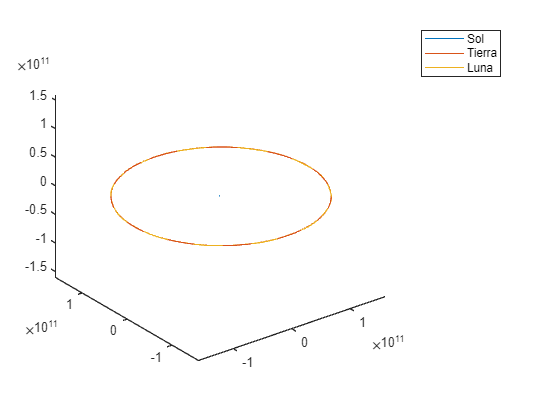

h = 60*60*24; % Cantidad de Segundos en un día
tf=365*h; %Un año
[resT,resY] = RK4(f,0,tf,y0,h);
n=length(resY(:,1));
for i=1:3:(n/2)-2
    plot3(resY(i,:),resY(i+1,:),resY(i+2,:))
    hold on
end
legend('Sol','Tierra','Luna')
vGI=1.6e11;
axis([-vGI +vGI -vGI +vGI -vGI +vGI])
hold off

Podemos notar en la gráfica un pequeño punto en el centro y alrrededor una órbita que cambia de color denotando la tierra y la luna. Es claro que en comparación con la distancia que existe entre el sol y esta órbita, la distancia tierra-luna será despreciable, para ello buscaremos graficar solo estos dos cuerpos en un periodo menor. 

### Prueba 2

Gráfica de las posiciones de la Tierra y la Luna del 1ero al 17mo de febrero de 2023, lo equivalente a dos ciclos lunares.

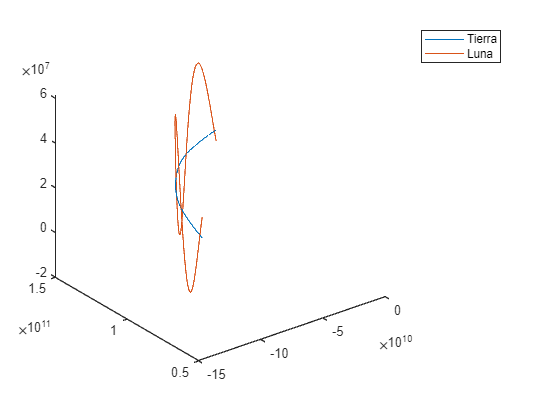

h = 60*60; % Va a evaluar cada hora
tf=28*24*h*2; %Para calcular dos ciclos lunares. 
[resT,resY] = RK4(f,0,tf,y0,h);
for i=4:3:7
    plot3(resY(i,:),resY(i+1,:),resY(i+2,:))
    hold on
end
legend('Tierra','Luna')
hold off

Podemos notar que efectivamente la luna oscila alrrededor de la tierra. Podría parecer en un principio que suba y baja más de lo que cambia en el plano perpendicular a este, sin embargo si notamos las magnitudes de los ejes, el aumento en esta dirección es mucho menor. Si hicieramos un zoom con alta presición notaríamos que está haciando una especie de espiral alrrededor de la trayectoria de la Tierra. 

### Prueba 3

Tierra y Luna el 1ero de enero desde las 0:00 hasta las 24:00

h = 60; % Va a evaluar cada minuto
tf=60*24*h %Para calcular un dia

tf = 86400

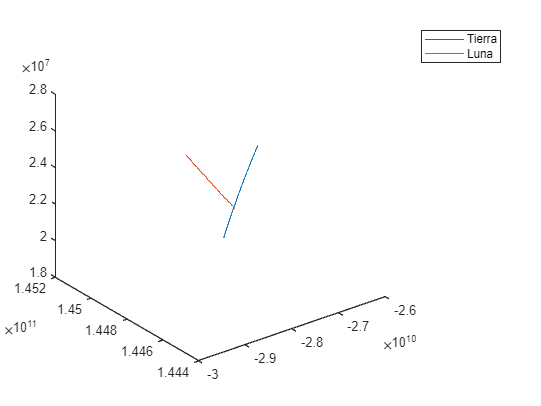

[resT,resY] = RK4(f,0,tf,y0,h);
for i=4:3:7
    plot3(resY(i,:),resY(i+1,:),resY(i+2,:))
    hold on
end
legend('Tierra','Luna')
hold off

Podemos observar que conforme la tierra (azul) se traslada un día, la tierra gira una pequeña parte a su allededor, digamos hace un arco que es un fragmento de la órbita espiral. Si recordamos la prueba 2, notamos que en el ciclo lunar es cuando se completa un giro de la luna alrrededor de la tierra. 

### Prueba 4

Con esta prueba utilizaremos una función de autoría propia que recibe las condiciones iniciales de posición, velocidad, la relación constante G*masa y el tiempo, a lo largo del cual queremos buscar estos en años y devuelve las distancias y sus respectivos tiempos. 

En esta prueba estamos utilizando un periodo de 100 años y queremos encontrar las distancias mínimas y máximas entre cada uno de los cuerpos celestes y los tiempos (año) en que sucede. 

 [mini,indMin,maxi,indMax] = minMax(100,y0, Gm);

Tomando en cuenta el periodo que va desde 0.000000 hasta 100.000000 años
 La distancia mínima y máxima entre el sol y la tierra son 147090436379.964294 y 152110279836.575806 metros 
 respectivamente y suceden en los tiempos (años) 53.049315 y 49.545205.
 La distancia mínima y máxima entre el sol y la luna son 146435065040.091034 y 166194427734.892639 metros 
 respectivamente y suceden en los tiempos (años) 36.035616 y 93.684932.
 La distancia mínima y máxima entre la tierra y la luna son 179539481.163794 y 313331384324.552734 metros 
 respectivamente y suceden en los tiempos (años) 51.745205 y 98.016438.

Es interesante notar como la distancia máxima y mínima entre el sol y la tierra suceden en un periodo de tan solo 4 años de diferencia. Cuando para los otros las diferencias en tiempo superan los 40 años. 

## CONCLUSIONES

En el presente trabajo logramos reforzar muchos de los conocimientos que habíamos adquirido a lo largo del curso. En primer lugar, tenemos las ODEs, que fueron una herramienta muy útil para aproximar valores. En este caso, las aplicamos para encontrar las posiciones del sol, la tierra y la luna. En segundo lugar, reforzamos los conocimientos de física sobre la velocidad, aceleración y posición, con sus relaciones matemáticas de derivadas e integrales. Por último, entendimos el comportamiento de los cuerpos celestes anteriormente mencionados.

Para llegar al resultado final del proyecto, nos enfrentamos con algunos desafíos. Inicialmente el problema fue comprender el modelo matemático. Esto fundamental, ya que de ahí se derivaba el resto del trabajo. También tuvimos dificultades con la creación de las funciones, junto con la elección de qué función era la más adecuada para cada caso. En ocasiones fue complicado establecer las unidades, ya que utilizábamos tanto años, como días. Ya que la distancia Sol-Tierra es demasiado grande, nos enfrentamos con el problema de dudar de nuestra solución debido a que el movimiento de la Luna se volvía imperceptible. A pesar de estos tropiezos, logramos terminar el proyecto satisfactoriamente y con nuestro mayor esfuerzo.

## REFERENCIAS

- Solar System Dynamics from NASA Jet Propulsory Laboratory

- Njeunje, J. (2018). The equations of planetary motion and their numerical solution. *Western Illinois University*. Recuperado el 28 de abril de 2023 de: [http://www.wiu.edu/cas/mathematics_and_philosophy/graduate/equations-planetary-motion.pdf](http://www.wiu.edu/cas/mathematics_and_philosophy/graduate/equations-planetary-motion.pdf)

## FUNCIONES

Movimiento Planetario

function f=movimientoPlanetario(Gm,rv)
    n=length(rv);
    f=zeros(size(rv));
    nMed=n/2;
    f(1:nMed)=rv(nMed+1:end);
    for i=1:3:nMed-2
        f(nMed+i:nMed+i+2)=aceleracion(Gm,rv,i);
    end
end

Aceleración

function a=aceleracion(Gm,rv,alpha)
    a=zeros(3,1);
    j=1;
    for i=1:3:((length(rv)/2)-2)
        if i~=alpha
            r=[0;0;0];
            r(1)=rv(i)-rv(alpha);
            r(2)=rv(i+1)-rv(alpha+1);
            r(3)=rv(i+2)-rv(alpha+2);
            rN=norm(r);
            a=a+(Gm(j)/rN^3)*r;
        end
        j=j+1;
    end
end

RK4

function [t,y]=RK4(f,t0,tf,y0,h)
   
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0),n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+(h/2),y(:,i)+(h/2)*k1);
        k3=f(t(i)+(h/2),y(:,i)+0.5*k2*h);
        k4=f(t(i)+(h/2),y(:,i)+k2*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end

ode RFF45

function [t,y]=odeRKF45(f,t0,tf,y0,h)
   
    i=1;
    t(i)=t0;
    y(:,i)=y0;
    max=1000;
    reTol=10^-6;
    while t(end)<tf && i< max
        [zi,re]=rkf45step(f,t(end),y(:, end),h);
        if re <=reTol
            t(end+1)=t(end)+h;
            y(:,end+1)=zi;
            i=i+1;
        end
        h=0.9*h*nthroot(reTol/re,5);
    end
end

    function [zi,re] = rkf45step(f,t,w,h) %1 solo paso
        s1=f(t,w);
        s2=f(t+(1/4)*h,w+(1/4)*h*s1);
        s3=f(t+(3/8)*h,w+(3/32)*h*s1+(9/32)*h*s2);
        s4=f(t+(12/13)*h,w+(1932/2197)*h*s1-(7200/2197)*h*s2+(7296/2197)*h*s3);
        s5=f(t+h,w+(439/216)*h*s1-8*h*s2+(3680/513)*h*s3-(845/4104)*h*s4);
        s6=f(t+(1/2)*h,w-(8/27)*h*s1+2*h*s2-(3544/2565)*h*s3+(1859/4104)*h*s4-(11/40)*h*s5);

        wi=w+h*((25/216)*s1+(1408/2565)*s3+(2197/4104)*s4-(1/5)*s5);
        zi=w+h*((16/135)*s1+(6656/12825)*s3+(28561/56430)*s4-(9/50)*s5+(2/55)*s6);
        re=norm((zi-wi)./zi,Inf);
    end

ABM4

function [t,y] = ABM4(f,y0,t0,tf,h)
    steps=4;
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0),n);
    fv=zeros(size(y));
    [~,y(:,1:steps)]=RK4(f,t0,t(steps),y0,h);%(f,t0,tf,y0,h)
    fv(:,1:steps)=bsxfun(f,t(1:steps),y(:,1:steps));
    for i=steps:(n-1)
        y(:,i+1)=y(:,i)+(h/24)*(55*fv(:,i)-59*fv(:,i-1)+37*fv(:,i-2)-9*fv(:,i-3));
        fv(:,i+1)=f(t(i+1),y(:,i+1));
        y(:,i+1)=y(:,i)+(h/24)*(9*fv(:,i+1)+19*fv(:,i)-5*fv(:,i-1)+fv(:,i-2));
        fv(:,i+1)=f(t(i+1),y(:,i+1));
    end
end


Funcion MinMax

function [mini,indMini,maxi,indMaxi]=minMax(tf,y0,Gm)
    
    h=60*60*24;
    fPlanetas=@(t,y)movimientoPlanetario(Gm,y);
    tfOde=h*365*tf;
    [t,y]=RK4(fPlanetas,0,tfOde,y0,h);
    
    n=length(y(1,:));
    dST=zeros(3,n);
    dSL=zeros(3,n);
    dTL=zeros(3,n);
    for i=1:3
        dST(i,:)=y(i,:)-y(3+i,:);
        dSL(i,:)=y(i,:)-y(6+i,:);
        dTL(i,:)=y(3+i,:)-y(6+i,:);
    end
    for i = 1:n
        vecnormST(i) =  norm([dST(1,i),dST(2,i),dST(3,i)]);
        vecnormSL(i) =  norm([dSL(1,i),dSL(2,i),dSL(3,i)]);
        vecnormTL(i) =  norm([dTL(1,i),dTL(2,i),dTL(3,i)]);
    end
    
    [mini(1),indMini(1)]=min(vecnormST);
    [mini(2),indMini(2)]=min(vecnormSL);
    [mini(3),indMini(3)]=min(vecnormTL);
    [maxi(1),indMaxi(1)]=max(vecnormST);
    [maxi(2),indMaxi(2)]=max(vecnormSL);
    [maxi(3),indMaxi(3)]=max(vecnormTL);
   
    fprintf("Tomando en cuenta el periodo que va desde %f hasta %f años",0,tf)
    fprintf("\n La distancia mínima y máxima entre el sol y la tierra son %f y %f metros \n respectivamente y suceden en los tiempos (años) %f y %f.",mini(1),maxi(1),t(indMini(1))/(365*h),t(indMaxi(1))/(365*h))
    fprintf("\n La distancia mínima y máxima entre el sol y la luna son %f y %f metros \n respectivamente y suceden en los tiempos (años) %f y %f.",mini(2),maxi(2),t(indMini(2))/(365*h),t(indMaxi(2))/(365*h))
    fprintf("\n La distancia mínima y máxima entre la tierra y la luna son %f y %f metros \n respectivamente y suceden en los tiempos (años) %f y %f.",mini(3),maxi(3),t(indMini(3))/(365*h),t(indMaxi(3))/(365*h))
end
